# SINDy bifurcation parameters

- Learn the logistic map from data at 10 bifurcation parameters

- Generate the full logistic map from the learned SINDy model

- The same idea of extending the time series data matrix with a parameter vecotr can be applied to systems with control 

## Generate Data: Logistic map at 10 different $\mu \;$

addpath(genpath(pwd))

% parameters
nStep = 1000; % number of discrete time steps
mu = [2.5, 2.75, 3, 3.25, 3.5, 3.75, 3.8, 3.85, 3.9, 3.95]';
mus = repmat(mu,1,nStep+1);
lmus = length(mu);

xn1_lm = zeros(lmus,nStep+1);
x0 = 0.5; % initial condition
xn1_lm(:,1) = x0; 

eta = 0.025; % magnitude stochastic forcing: Gaussian

% integrate discrete time dynamics
rng(1)
for j = 1:lmus
    for i = 1:nStep
        xn1 = mus(j,i)*xn1_lm(j,i)*(1-xn1_lm(j,i))+eta*randn(1);
        xn1_lm(j,i+1) = max([min([xn1,1]),0]);
    end
end



## Compute Derivative and define parameter array 

- dx: simply shift state

- u: bifurcation parameter $\mu \;$(or control input)

x = xn1_lm(:,1:end-1); % state x
u = mus(:,1:end-1); % parameter mu
dx = xn1_lm(:,2:end); % left hand side: time shifted state x

xu = [x(:), u(:)]; % u is added to the stacked data matrix 
dx = [dx(:), zeros(nStep*lmus,1)]; % "derivatives", time shifted x, and zero for mu


## Build library of nonlinear time series

n = 2; % number of states
polyorder = 3; % polynomials up to order 3
Theta = poolData(xu,n,polyorder);
m = size(Theta,2); % size of library


## SINDy

lambda = 0.1;      % lambda is our sparsification knob.
Xi = sparsifyDynamics(Theta,dx,lambda,n); % identify model coefficients
disp(poolDataLIST({'x','u'},Xi,n,polyorder)) % display SINDy model

    {0×0 char}    {'xdot'   }    {'udot'}
    {'1'     }    {[      0]}    {[   0]}
    {'x'     }    {[      0]}    {[   0]}
    {'u'     }    {[      0]}    {[   0]}
    {'xx'    }    {[      0]}    {[   0]}
    {'xu'    }    {[ 0.9997]}    {[   0]}
    {'uu'    }    {[      0]}    {[   0]}
    {'xxx'   }    {[      0]}    {[   0]}
    {'xxu'   }    {[-0.9997]}    {[   0]}
    {'xuu'   }    {[      0]}    {[   0]}
    {'uuu'   }    {[      0]}    {[   0]}



## Evaluate identified model at different bifurcation parameters $\mu \;$

paramSINDy.Xi = Xi;
paramSINDy.polyorder = polyorder;
testmus = 0:0.001:4; % evaluate model at these parameters mu
ltestmus = length(testmus);

nStep = 1000; % number of discrete time steps
mus = repmat(testmus',1,nStep+1);

xn1_SINDy = zeros(ltestmus,nStep+1);
xn1_SINDy(:,1) = x0;
for j = 1:ltestmus
    for i = 1:nStep
        xn1 = SINDyODE(0,[xn1_SINDy(j,i);mus(j,i)],paramSINDy);
        xn1_SINDy(j,i+1) = max([min([xn1(1),1]),0]);
    end
end


## Plot logistic map

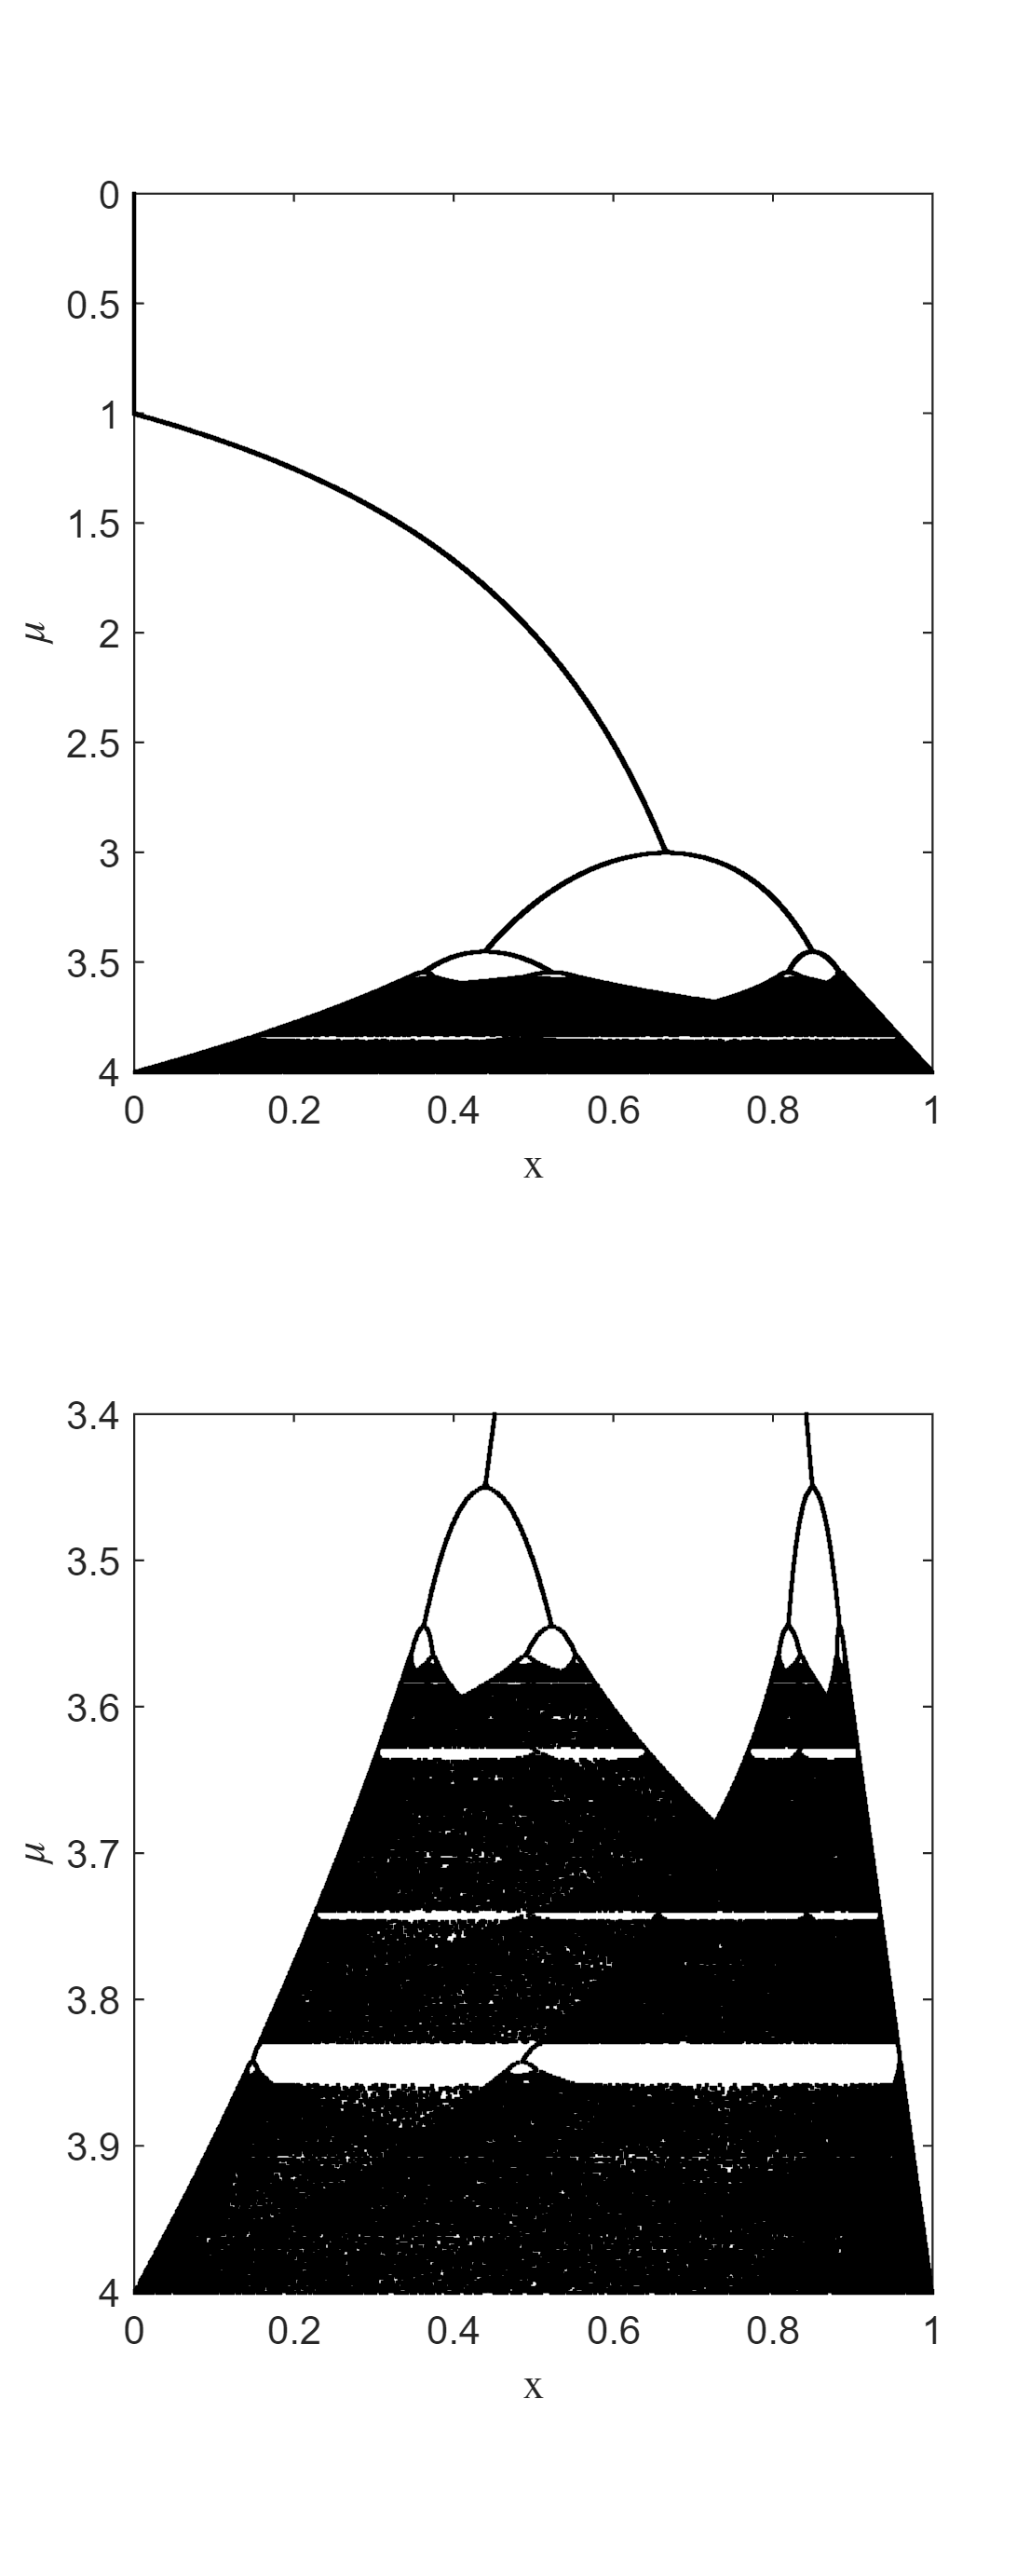

xPlot = xn1_SINDy(:,500:end); % remove the transient
muPlot = mus(:,500:end);
figure('units','pixels','position',[50 50 400 1000])
subplot(2,1,1)
plot(xPlot(:),muPlot(:),'.', 'LineWidth', .1, 'MarkerSize',1.2,'Color',[0 0 0])
set(gca,'YDir','reverse');
xlabel('x','Interpreter','latex')
ylabel('$\mu$','Interpreter','latex')
subplot(2,1,2)
plot(xPlot(:),muPlot(:),'.', 'LineWidth', .1, 'MarkerSize',1.2,'Color',[0 0 0])
set(gca,'YDir','reverse');
ylim([3.4 4])
xlabel('x','Interpreter','latex')
ylabel('$\mu$','Interpreter','latex')